# On the Optimality of Spectrally Notched Radar Waveform & Filter Designs

Jonathan W. Owen, Patrick M. McCormick, Christian C. Jones, Shannon D. Blunt, Radar Systems Lab (RSL), University of Kansas, Lawrence, KS

M = 256; % signal length

% Desired Autocorrelation (all zeros except a single one)
desiredAutocorr = zeros(M,1);
desiredAutocorr(1) = 1;

% Inverse DFT matrix
% A is the inverse DFT matrix which is just the Hermitian transpose of the DFT matrix
% I also normalize it by M
A = dftmtx(M)'/M;

% Spoiling the IDFT matrix
% < 0 means no spoiling
for n = 0:15
    Aspoil = A;
    if n > 0
        Aspoil(2:2+n-1,:) = 0;
        Aspoil(end-n+1:end,:) = 0;
    end


## Objective Function

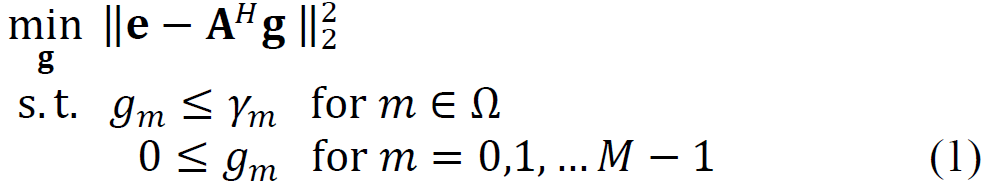

Lets take a look at the objective function and constraints above.

- **e** is the desired autocorrelation function, i.e. a single 1 and the rest 0's.

- **g** is the power spectral density (PSD) of the waveform

- **A** is the DFT matrix which means that its Hermitian transpose is the inverse DFT matrix.

- The PSD is the Fourier Transform of the autocorrelation. Thus, we are minimizing the difference between the desired autocorrelation, **e**, and the autocorrelation of the waveform with PSD, **g**.

- The first inequality constraint is ensures that the frequency regions, $\Omega \;,$ are not used for transmission. Specifically, it ensures that the PSD for those frequencies are below $\gamma \;\ldotp$ 

- The second inequality constraint ensures that for all frequencies, the PSD is nonnegative.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

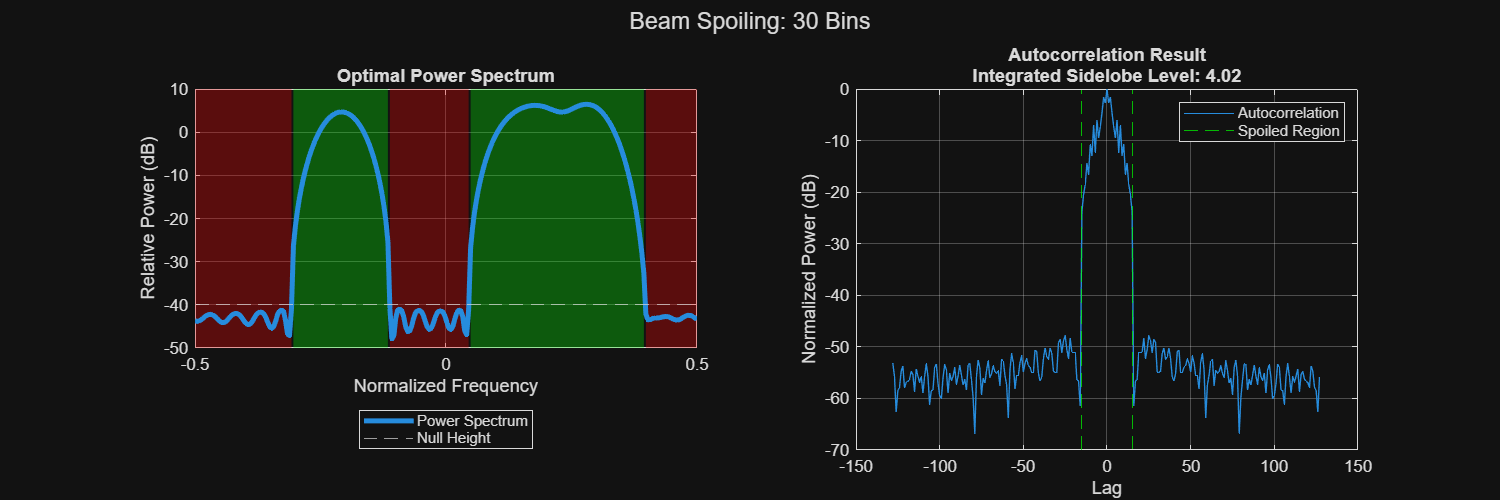

    % Equation 1 in paper
    % g is the desired PSD which is the FT of the autocorelation
    fun = @(g)norm(desiredAutocorr-Aspoil*g,2);
    
    lb = zeros(size(desiredAutocorr)); % lower bound
    ub = inf(size(desiredAutocorr)); % upper bound
    
    nullHeight = db2pow(-40); % how low the nulls should be set to (power)
    
    % Create desired spectrum by constraining upper bound
    nulls = [[1 50];[100 140];[230 M]]';
    for null = nulls
        ub(null(1):null(2)) = nullHeight;
    end
    ub = fftshift(ub);
    
    x0 = zeros(size(desiredAutocorr)); % initial point in optimization process
    options = optimoptions('fmincon',MaxFunctionEvaluations=100000);
    % A, b, Aeq, beq, nonlcon are not relevant so they are all set to empty
    g = fmincon(fun,x0,[],[],[],[],lb,ub,[],options);
    if n == 0
        % Create figure and axes
        f = figure;
        f.Position(3:4) = [1200 400];
    
        % ===== Left subplot: Power Spectrum =====
        subplot(1,2,1)
        ax1 = gca;
        x = linspace(-.5, .5, M);
        psData = fftshift(pow2db(g));
        psAx = plot(ax1, x, psData, 'LineWidth', 3);
        plot_null_patches(ax1, nulls', x, M);
        hold on;
        nullHeightAx = yline(ax1, pow2db(nullHeight), '--');
        grid on;
        xlabel('Normalized Frequency')
        ylabel('Relative Power (dB)')
        title('Optimal Power Spectrum')
        legend(ax1, [psAx, nullHeightAx], ...
               {'Power Spectrum', 'Null Height'}, ...
               'Location', 'southoutside');
    
        % ===== Right subplot: Autocorrelation =====
        subplot(1,2,2)
        axAC = gca;
        autocorrResult = pow2db(fftshift(abs(A' * g)));
        [psl, isl] = sidelobelevel(autocorrResult);
        autocorrAx = plot(axAC,-M/2:M/2-1, autocorrResult);
        hold on
        vertLines = xline(axAC,NaN*[-1 1],'DisplayName','Spoiled Region','Color','green','LineStyle','--');
        grid on;
        xlabel('Lag')
        ylabel('Normalized Power (dB)')
        ylim([-70 0])
        title({'Autocorrelation Result', ...
               sprintf('Integrated Sidelobe Level: %.2f', isl)})
        legend(axAC,{'Autocorrelation','Spoiled Region'}, 'Location', 'northeast');

    else
        % Update data without redoing full setup
        psAx.YData = fftshift(pow2db(g));
        nullHeightAx.Value = pow2db(nullHeight);
        vertLines(1).Value = -n;
        vertLines(2).Value = n;
        autocorrResult = pow2db(fftshift(abs(A' * g)));
        autocorrAx.YData = autocorrResult;
        [~, isl] = sidelobelevel(autocorrResult);
        title(axAC, {'Autocorrelation Result', ...
                     sprintf('Integrated Sidelobe Level: %.2f', isl)});

    end
    sgtitle(sprintf('Beam Spoiling: %d Bins',2*n))    
    link_all_patches_ylim(ax1)
    pause(.5)
end

function plot_null_patches(ax, nulls,x,M)
    % Get y-axis limits
    yl = ylim;

    % Step 1: create mask for red (null) regions
    mask = false(1, M);
    for k = 1:size(nulls, 1)
        mask(nulls(k,1):nulls(k,2)) = true;
    end
    
    % Step 2: find continuous regions for red and green
    red_intervals = mask_to_intervals(mask);
    green_intervals = mask_to_intervals(~mask);
    
    % Step 3: plot patches
    for k = 1:size(red_intervals, 1)
        patchHandle = patch(ax,[x(red_intervals(k,1)) x(red_intervals(k,2)) x(red_intervals(k,2)) x(red_intervals(k,1))], ...
              [yl(1) yl(1) yl(2) yl(2)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
        uistack(patchHandle, 'bottom');
    end
    
    for k = 1:size(green_intervals, 1)
        patchHandle = patch(ax,[x(green_intervals(k,1)) x(green_intervals(k,2)) x(green_intervals(k,2)) x(green_intervals(k,1))], ...
              [yl(1) yl(1) yl(2) yl(2)], 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
        uistack(patchHandle, 'bottom');
    end
    
    hold off;
end

% ===== Helper function =====
function intervals = mask_to_intervals(mask)
    % Finds start/end indices of contiguous true regions
    d = diff([false mask false]);
    starts = find(d == 1);
    ends   = find(d == -1) - 1;
    intervals = [starts(:) ends(:)];
end

function link_all_patches_ylim(ax)
    % Get all patches in the axes
    patchHandles = findobj(ax, 'Type', 'patch');

    % Define the listener callback
    function updateY(~, ~)
        yl = ylim(ax);
        for p = patchHandles(:)'
            xd = get(p, 'XData');
            set(p, 'YData', [yl(1) yl(1) yl(2) yl(2)]);
            set(p, 'XData', xd); % ensure X stays the same
        end
    end

    % Initial update
    updateY();

    % Add listener to the axes
    addlistener(ax, 'YLim', 'PostSet', @updateY);
end